# ACM 11 Week 3: In-class activity

#### Names of all group members: 

Dallas Taylor

We consider the formation of nitric oxide (${\textrm{NO}}_{\left(g\right)}$), an undesireable pollutant, as a byproduct of combustions of methane (natural gas) with air in the following reaction:


$${\textrm{CH}}_{4,\left(g\right)} +3\left({\mathrm{O}}_{2,\left(g\right)} +4N_{2,\left(g\right)} \right)\to {\textrm{CO}}_{2,\left(g\right)} +2{\mathrm{H}}_2 {\mathrm{O}}_{\left(l\right)} +12{\mathrm{N}}_{2,\left(g\right)} +{\mathrm{O}}_{2,\left(g\right)}$$


The product gas mixture exits the combustion chamber at 2000 K and has a specific heat capacity $c_{\prod } =30\ldotp 5\;\frac{\mathrm{J}}{\mathrm{K}\cdot \textrm{mol}}$. We are interested in the formation of nitric oxide from the excess nitrogen and oxygen in the following reaction:


$${\mathrm{N}}_{2,\left(g\right)} +{\mathrm{O}}_{2,\left(g\right)} +\Delta H^{\circ } \to 2{\textrm{NO}}_{\left(g\right)} \;\;\;\;\;\;\;\;\;\;\;\left(1\right)$$


where $\Delta H^{\circ } =180500\;\mathrm{J}$, i.e. the reaction is endothermic. We assume that the gases reach equilibrium after exiting, and we want to know $x$, the number of moles of ${\textrm{NO}}_{\left(g\right)}$ formed per mole of methane combusted. The equilibrium constant for the reaction in eq. (1) is a function of temperature given by


$$K_{\textrm{eq}} \left(T\right)=20\ldotp 2\;\exp \left(\Delta H^{\circ } /\left(\textrm{RT}\right)\right)=\frac{{\left\lbrack {\textrm{NO}}_{\left(g\right)} \right\rbrack }^2 }{\left\lbrack {\mathrm{N}}_{2,\left(g\right)} \right\rbrack \left\lbrack {\mathrm{O}}_{2,\left(g\right)} \right\rbrack }=\frac{x^2 }{\left(12-0\ldotp 5x\right)\left(1-0\ldotp 5x\right)}\;\;\;\;\;\left(2\right)$$


where $R=8\ldotp 314$$\text{J/(mol-K)}$, the ideal gas constant. Since the reaction is endothermic, we know that


$$T=2000-\frac{\Delta H^{\circ } }{2\cdot \left(14\cdot c_{\prod } \right)}x\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(3\right)$$


At equilibrium, eqns. (2) and (3) hold. Combining the expressions in eqns. (2) and (3), we obatin and expression in the form $f\left(x\right)=0$ at equilibirum.

clear
close all

Constants below for the reaction are defined below.

k0 = 4.629e-31; % N2 + O2 -> 2NO equilibrium constant at 298 K
dH = 180500;    % N2 + O2 -> 2NO [J] heat of reaction
R = 8.314;      % [J/K-mol] ideal gas constant

Temp = @(x) 2000-dH/(28*30.5)*x;    % temperature as a function of x, number of moles of NO

C    = k0*exp(dH/(R*298));          % Keq exponential pre-factor
Keq  = @(T) C*exp(-dH./(R*T));      % Keq as a function of temperature (use Temp to calculate)
f = @(x) Keq(Temp(x)).*(12-0.5*x).*(1-0.5*x) - x.^2;

For this activity, we have provided the functions `bisection`, `newton`, and `fpi. `You can look at the in-class demos for examples of how to call these functions.

**Part 1 (Bisection): **Use `bisection.m` to find $x$, the number of moles of ${\textrm{NO}}_{\left(g\right)}$ at equilibrium. Use $\tau=1\text {e-}6$, $N_{max}=20$, $x_l=1\text {e-}6$, and $x_r =2$ (note that we can make 2 moles of $\textrm{NO}$ with the one mole of oxygen in the product gas mixture). What is $x$ at equilibrium? 

X at equilibrium is 0.0647.

x_bisect = bisection(f,10^-6,2,10^-6,20);    % fill in here
x_bisect(end) % show final answer

ans = 0.0647

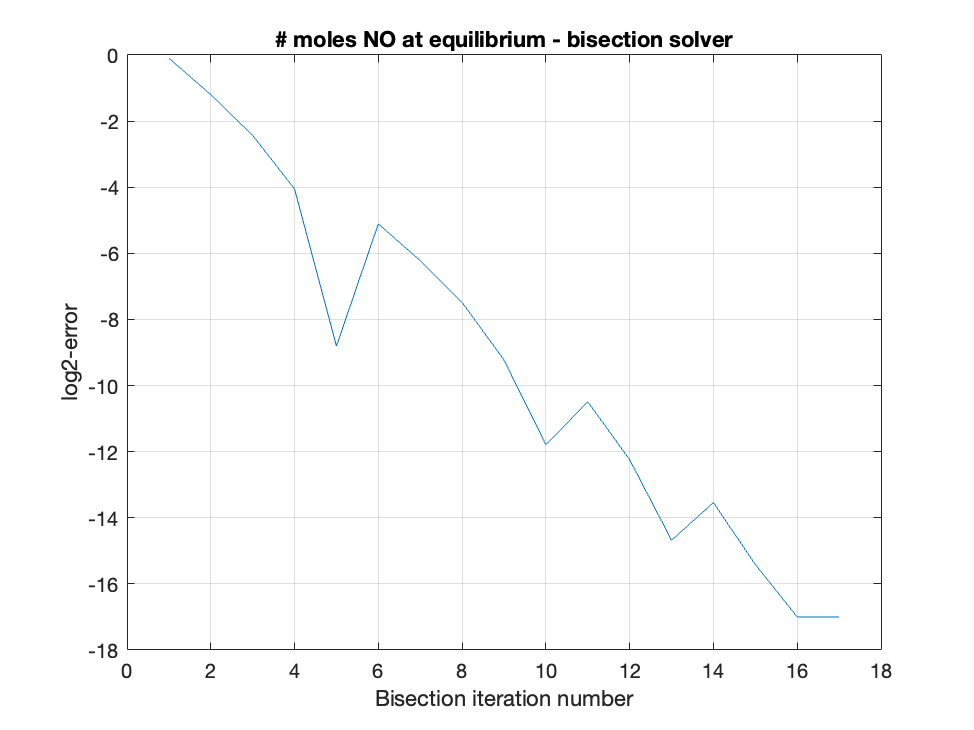


% plot
figure(1); clf
plot(log2(abs(x_bisect-x_bisect(end)))); grid on
xlabel('Bisection iteration number')
ylabel('log2-error')
title('# moles NO at equilibrium - bisection solver')

We have plotted the error, $\log_2 \left|x_n -x_{\textrm{truth}} \right|$ vs. iteration number. What is the average slope of this plot? (Eyeballing it is fine.) What does this mean about the average rate of error decay per iteration?

The average slope of this plot seems to be about -1.  This means that the average rate of decay per iteration is 1? (I don't know im confused what rate of decay is).  I know that this means that the log2-error decays by the same amount for each iteration.  Perhaps this means that that it is decaying by a factor of 2.

**Part 2 (fixed point iteration): **Recast the $f\left(x\right)=0$ root-finding problem as a $g\left(x\right)=x$ fixed point iteration. We define a good $g\left(x\right)$ for you. Use a tolerance of $\tau ={10}^{-6}$ and a max iteration count of 20.

tau = 10^-6;
Nmax = 20;
% define function for FPI
g = @(x) sqrt(Keq(Temp(x)).*(12-0.5*x).*(1-0.5*x));
xt = logspace(-4,-1);

Use `fpi.m` to solve this problem. Does your answer here match your answer using `bisection.m` ?

x_fpi = fpi(g,xt,tau,Nmax);   % fill in here
x_fpi(end)  % show final answer

ans = 0.0647

The answer here is the same from when useing bisection.m.  ans = 0.0647.

**Part 3 (Newton iteration): **We have provided the function `newton.m` with the Newton iteration update step and convergence condition to break the iteration. Below is a function `J` that uses the secant approximation to compute the Jacobian of the function $f$ defined above. 

% eps is a MATLAB hard-coded variable that is a very small number
J = @(x) (f(x+eps) - f(x-eps))/(2*eps);

Call `newton.m` to solve for $x$, using $x_0 =0\ldotp 1$ and $x_0 =0\ldotp 5$ as initial conditions. How many iterations does the solver take to converge using each of these intial guesses? Use a tolerance of $\tau ={10}^{-6}$ and max iteration count of 20.

x0_a = 0.1;
x_newton_a = newton(f,J,x0_a,tau,Nmax);  % fill in here
x_newton_a(end) % show final_answer

ans = 0.0647


x0_b = 0.5;
x_newton_b = newton(f,J,x0_b,tau,Nmax);  % fill in here
x_newton_b(end) % show final answer

ans = 0.0647

It takes the solver 2 iterations for when x_0 = 0.1, and 5 iterations for when x_0 = 0.5.

Below, we have plotted the error for the Newton solver for the two initial conditions.

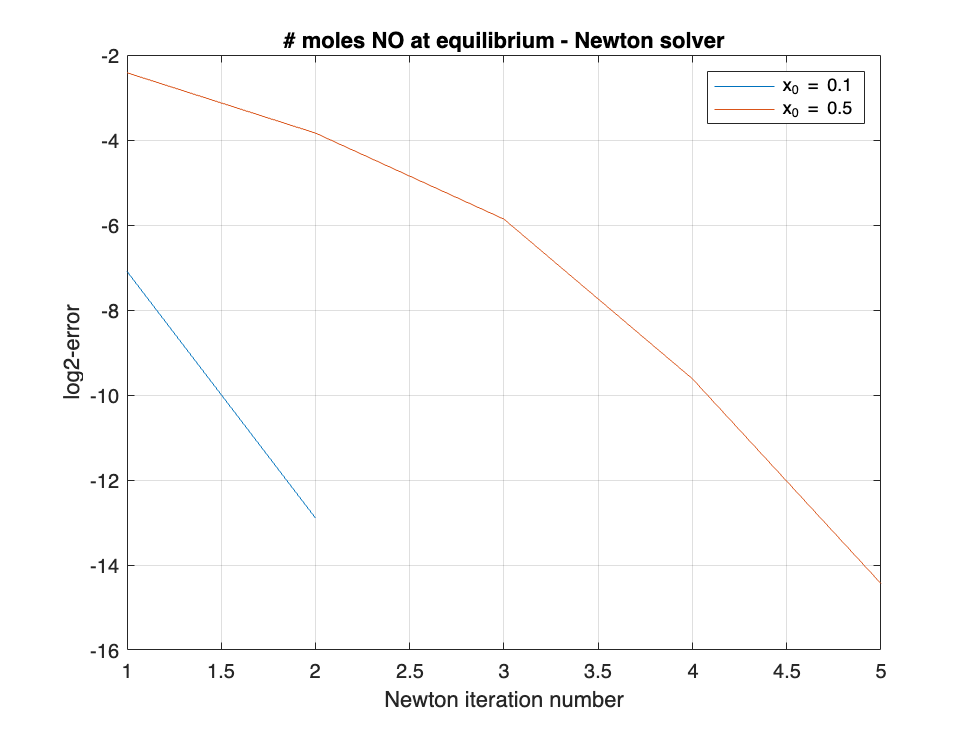

figure(3); clf
plot(log2(abs(x_newton_a-x_newton_a(end)))); grid on; hold on
plot(log2(abs(x_newton_b-x_newton_b(end))));
xlabel('Newton iteration number')
ylabel('log2-error')
legend('x_0 = 0.1','x_0 = 0.5')
title('# moles NO at equilibrium - Newton solver')

Which initial condition leads to faster Newton convergence? Why do you think that is?

I think that the initial condition of x_0 = 0.1 leads to faster convergence  since we are much closer to our desired equilibrium value.  Thus, we are able to quickly reach our desired value. 